# Descending 1_CCRN_1_cat 

Read reaction network

foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat - Copy"

filnam = "Evolution - Praful\1_CCRN_1_cat - Copy"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat - Copy"

model_nam = "1-CCRN-1-cat - Copy"

[num_spec,species,comp_vec,rxn_rate,G] = extract_rxn_net(filnam);

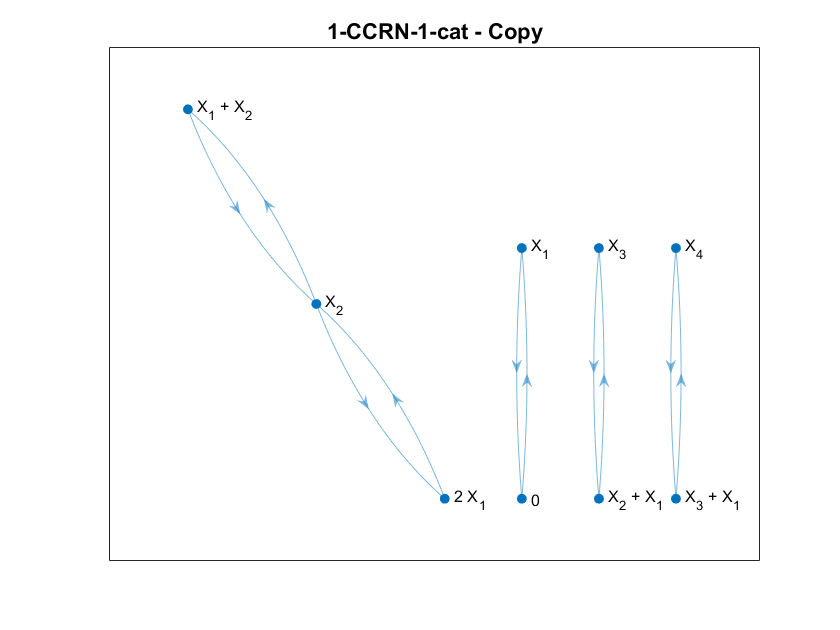

plotter(G,model_nam)
saveas(gcf,foldernam + 'Plots\'+ model_nam + '_hypergraph.png')

%Get Hamiltonian
Ham = get_Hamiltonian(num_spec,comp_vec,rxn_rate)

$$Ham = 0.1476\,{\mathrm{e}}^{p_{1}}+q_{2}\,\left(2.9000\,{\mathrm{e}}^{p_{1}}-2.9000\right)+q_{1}\,\left({\mathrm{e}}^{-p_{1}}-1\right)+q_{2}\,\left(2.0600\,{\mathrm{e}}^{2\,p_{1}-p_{2}}-2.0600\right)+q_{3}\,\left(2.0600\,{\mathrm{e}}^{p_{1}+p_{2}-p_{3}}-2.0600\right)+q_{4}\,\left(2.0600\,{\mathrm{e}}^{p_{1}+p_{3}-p_{4}}-2.0600\right)+{q_{1}}^{2}\,\left({\mathrm{e}}^{p_{2}-2\,p_{1}}-1\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{p_{3}-p_{2}-p_{1}}-1\right)+q_{1}\,q_{3}\,\left({\mathrm{e}}^{p_{4}-p_{3}-p_{1}}-1\right)+q_{1}\,q_{2}\,\left({\mathrm{e}}^{-p_{1}}-1\right)-0.1476$$


%get functions derived from the Hamiltonian needed for the descent
Extract_Hamiltonian

%Get MAK polynomials and the jacobian
[MAK, jac, MAK_fun,MAK_fun_t, jac_fun] = get_MAK(dHamdp,Ham_qp_mix,num_spec);

$$MAK = \left(\begin{array}{c} 7.0200\,q_{2}-q_{1}+2.0600\,q_{3}+2.0600\,q_{4}-2\,q_{1}\,q_{2}-q_{1}\,q_{3}-2\,{q_{1}}^{2}+0.1476\\ {q_{1}}^{2}-q_{2}\,q_{1}-2.0600\,q_{2}+2.0600\,q_{3}\\ 2.0600\,q_{4}-2.0600\,q_{3}+q_{1}\,q_{2}-q_{1}\,q_{3}\\ q_{1}\,q_{3}-2.0600\,q_{4} \end{array}\right)$$

MAK_fun_t = function_handle with value:
    @(t,in2)[-in2(1,:)+in2(2,:).*(3.51e+2./5.0e+1)+in2(3,:).*(1.03e+2./5.0e+1)+in2(4,:).*(1.03e+2./5.0e+1)-in2(1,:).*in2(2,:).*2.0-in2(1,:).*in2(3,:)-in2(1,:).^2.*2.0+1.476e-1;in2(2,:).*(-1.03e+2./5.0e+1)+in2(3,:).*(1.03e+2./5.0e+1)-in2(1,:).*in2(2,:)+in2(1,:).^2;in2(3,:).*(-1.03e+2./5.0e+1)+in2(4,:).*(1.03e+2./5.0e+1)+in2(1,:).*in2(2,:)-in2(1,:).*in2(3,:);in2(4,:).*(-1.03e+2./5.0e+1)+in2(1,:).*in2(3,:)]



%save Hamiltonian data to file
save(foldernam + 'Data\' + model_nam + '_Ham.mat')


%get roots --- later replace this with Bertini
get_roots_2D

$$pos\_root\_arr = \left(\begin{array}{cccc} 0.7999 & 0.3106 & 0.1206 & 0.0468\\ 0.2001 & 0.0194 & 0.0019 & 1.8323e-04\\ 1.9000 & 1.7525 & 1.6164 & 1.4909 \end{array}\right)$$

$$pos\_root\_arr = \left(\begin{array}{cccc} 0.7999 & 0.3106 & 0.1206 & 0.0468\\ 0.2001 & 0.0194 & 0.0019 & 1.8323e-04\\ 1.9000 & 1.7525 & 1.6164 & 1.4909 \end{array}\right)$$

x_ic_arr =     0.7992    0.3099    0.1199    0.0461
    0.8006    0.3113    0.1213    0.0475


%saveas(gcf,foldernam + 'Plots\'+model_nam+'_stability.png')

spec_arr = 1:num_spec

spec_arr =      1     2     3     4


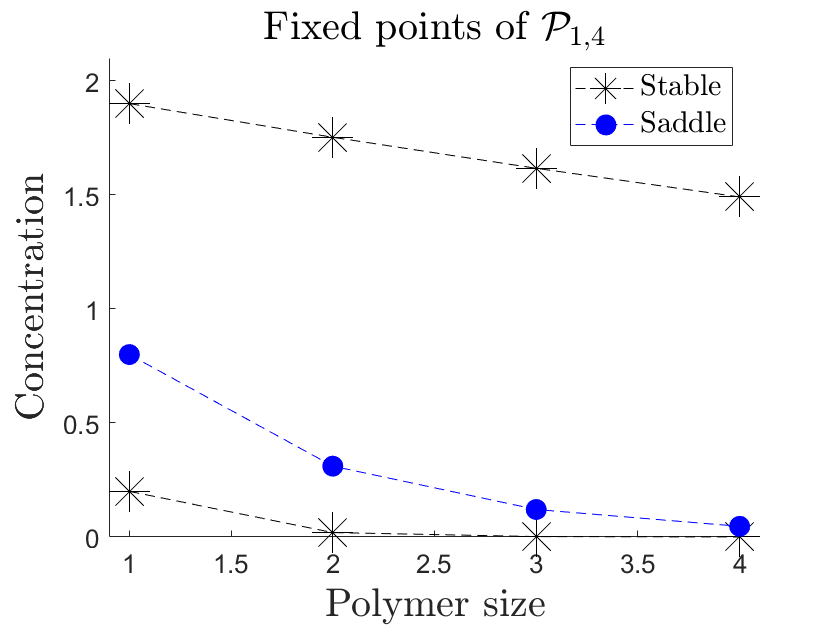

figure()
%lb = ; ub = 4;
hold on
plot(spec_arr, pos_root_arr(stab_idx(1),:),'k--*','MarkerSize',20,'MarkerFaceColor','k')
plot(spec_arr, pos_root_arr(sad_idx(1),:),'b--o','MarkerSize',10,'MarkerFaceColor','b')
%plot(pos_root_arr(2,1),pos_root_arr(2,2),'rs','MarkerSize',10,'MarkerFaceColor','r')
for i = 2:size(stab_idx,1)
    plot(spec_arr, pos_root_arr(stab_idx(i),:),'k--*','MarkerSize',20)
end
for i = 2:size(sad_idx,1)
    plot(spec_arr, pos_root_arr(sad_idx(i),:),'b--o','MarkerSize',10,'MarkerFaceColor','b')
end
hold off
%legend('Stable roots','Saddle roots','All roots','location','north')
h1=legend('Stable','Saddle','location','best');
%h1=legend('Stable','Saddle','location','best');
set(h1,'Interpreter','latex');
h1.FontSize = 15;
ax=gca;
ax.FontSize = 13;

xlabel('Polymer size','interpreter','latex','FontSize',20)
ylabel('Concentration','interpreter','latex','FontSize',20)
lim = double([min(pos_root_arr(:,1))-0.2  max(pos_root_arr(:,1))+0.2]);
xlim([0.9,4.1])
lim = double([min(pos_root_arr(:,2))-0.2  max(pos_root_arr(:,2))+1]);
ylim([0 2.1])
%grid on
title('Fixed points of $\mathcal{P}_{1,4}$','Interpreter','latex','FontSize',20)

pos_root_arr

$$pos\_root\_arr = \left(\begin{array}{cccc} 0.7999 & 0.3106 & 0.1206 & 0.0468\\ 0.2001 & 0.0194 & 0.0019 & 1.8323e-04\\ 1.9000 & 1.7525 & 1.6164 & 1.4909 \end{array}\right)$$

## Heteroclinic Network

Data saved in

'Examples\Data\' + model_name + '_hcnet.mat'

ans = "Computing time"

Elapsed time is 1.075859 seconds.


ans = "Computing time"

Elapsed time is 0.550859 seconds.


ans = "Simulation time"

ans = 618.7900

ans = "Computing time"

Elapsed time is 0.191565 seconds.


ans = "Simulation time"

ans = 163.9900

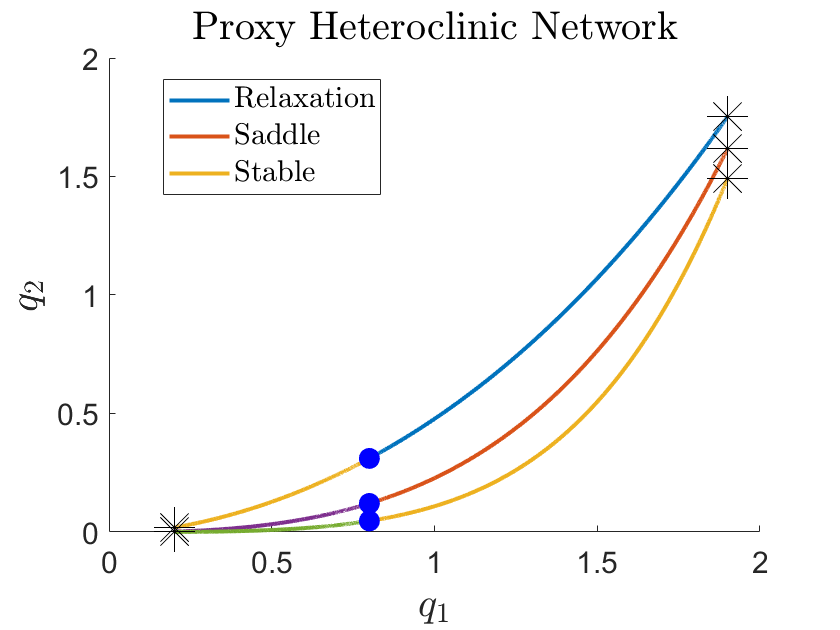

hc_net =      1     3     2


$$pos\_root\_arr = \left(\begin{array}{cccc} 0.7999 & 0.3106 & 0.1206 & 0.0468\\ 0.2001 & 0.0194 & 0.0019 & 1.8323e-04\\ 1.9000 & 1.7525 & 1.6164 & 1.4909 \end{array}\right)$$

t_max = 1000;
Heteroclinic_network

%save hc plot
saveas(gcf,foldernam +'Plots/'+model_nam+'_hcnet.png')


%Save hc_net data
save(foldernam + 'Data\' + model_nam + '_hcnet.mat','pos_root_arr', 'hc_net', 'hc_traj_arr', 'stab_idx', 'sad_idx','t_arr')
